# **Analisi PCA su dati di tumore ovarico**

s

### **Inizializzazione ed importazione dei dati**

clear all
close all
clc

load ovariancancer.mat;

Il dataset contiene:

- `obs `: spettri dei campioni

- `grp: `etichette ('Cancer', 'Normal')

size(obs)

ans =          216        4000


size(grp)

ans =    216     1


Per ciascuno dei 216 pazienti, dei quali 121 affetti da cancro e 95 no, è presente un vettore di dati contenente l'espressione di 4000 geni.

### Calcolo della PCA tramite SVD

[U, S, V] = svd(obs, 'econ');

Eseguendo la PCA tramite decomposizione ai valori singolari (SVD), osserviamo che una quota rilevante della varianza complessiva è concentrata nelle prime componenti principali. Questo significa che i dati genetici dei pazienti mostrano una forte ridondanza e correlazione, ovvero molte variabili (geni) variano insieme. 

#### Decrescita dei valori singolari

figure
subplot(1,2,1)
semilogy(diag(S), 'k-o', 'LineWidth', 1.5)
title('Spettro dei valori singolari (scala log)')
xlabel('Indice componente principale')
ylabel('Valore singolare (log)')
set(gca,'FontSize',11), axis tight, grid on

La decrescita rapida dei valori singolari indica che già le prime poche componenti principali catturano la maggior parte dell’informazione utile, mentre le componenti successive rappresentano solo dettagli marginali o rumore. 

#### Varianza cumulativa spiegata

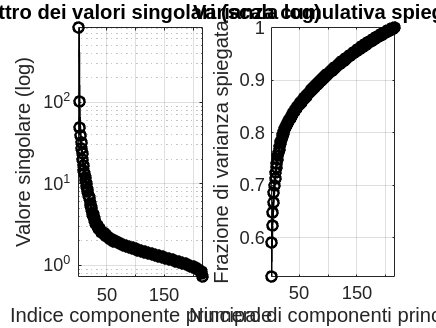

subplot(1,2,2)
varianza_cumulativa = cumsum(diag(S)) / sum(diag(S));
plot(varianza_cumulativa, 'k-o', 'LineWidth', 1.5)
title('Varianza cumulativa spiegata','FontSize',12)
xlabel('Numero di componenti principali')
ylabel('Frazione di varianza spiegata')
set(gca,'FontSize',11), axis tight, grid on

La curva cumulativa della varianza spiegata conferma questo comportamento, mostrando che è possibile rappresentare i dati in uno spazio a bassa dimensionalità senza perdite significative di informazione. In termini pratici, questo suggerisce che l’espressione genica dei pazienti tende a seguire pattern comuni, con sovrapposizioni evidenti tra individui, soprattutto tra quelli con caratteristiche biologiche simili.

### Proiezione 3D sulle Prime 3 Componenti Principali

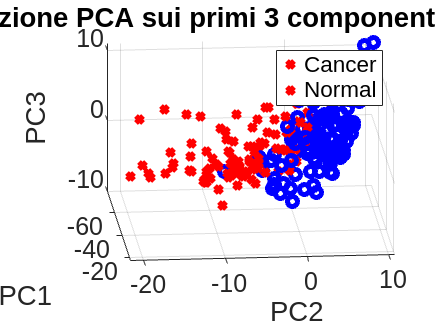

figure, hold on
for i = 1:size(obs,1)
    x = V(:,1)' * obs(i,:)';
    y = V(:,2)' * obs(i,:)';
    z = V(:,3)' * obs(i,:)';
    
    if(grp{i} == 'Cancer')
        plot3(x, y, z, 'rx', 'LineWidth', 3);
    else
        plot3(x, y, z, 'bo', 'LineWidth', 3);
    end
end

xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
title('Proiezione PCA sui primi 3 componenti principali','FontSize',11)
legend('Cancer','Normal')
view(85, 25)
grid on
set(gca,'FontSize',15)

## Conclusioni

- La **PCA** permette di ridurre la dimensionalità dei dati mantenendo la varianza principale.

- La **decrescita dei valori singolari** aiuta a capire quali componenti portano informazione e quali no.

- La **varianza cumulativa spiegata** è uno strumento utile per scegliere quante PC considerare.

- La rappresentazione 3D può evidenziare una **possibile separazione tra i gruppi Cancer e Normal**.